Y1 = readtable("X1+Y1/distances_not_scaled_by_area_Y1.csv");
Y1_df = readtable("Y1/Not_Scaled_Y1_df.csv");
Y1.Properties.RowNames = Y1.Var1;
Y1_df.Properties.RowNames = Y1_df.Var1;
Y1_cols = [
    0.0000, 0,      0;  %black    
0.0 1 1;      %cyan
    0.8000, 0,      1.0000; %purple
     0.3600,    0.6100,         0; %green
    1,      0.000, 0.0000; %red
 
    ];
Y1 = removevars(Y1, "Var1");
Y1_df = removevars(Y1_df, "Var1");
numericY1 = table2array(Y1);
% Display the first few rows of the Y1
N = max(size(numericY1));
nClusters = 4;


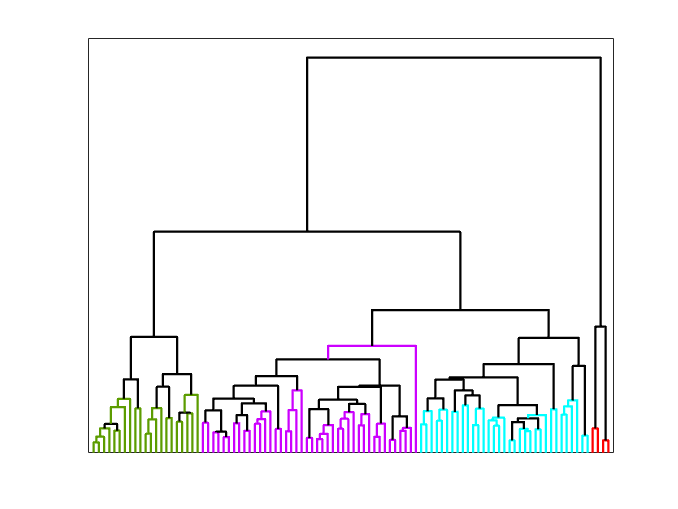

% Y1
% Generate HC with average linkage
%============================================
%
%============================================

tree1=linkage(numericY1,'average');

%
% Generate figure with 4 clusters
%
figure
cutoff = median([tree1(end-nClusters+1,3) tree1(end-nClusters+2, 3)]);
h1=dendrogram(tree1,0,'ColorThreshold',cutoff);
set(h1,'LineWidth',1.5);
xticks([])
yticks([])
% xlabel({"Y1 Average Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
%
% Collect colors
%
% We use four colors, that are in order:
% Cluster 1: red
% Cluster 2: purple
% Cluster 3: cyan
% Cluster 4: green
%
cyan=[0 1.0 1.0];
lineColours1 = cell2mat(get(h1,'Color'));
colorList1 = unique(lineColours1, 'rows');

%colorList(9,:) = [1 0 1];
for iLeaf = 1:N
	[iRow, ~] = find(tree1==iLeaf);
	color = lineColours1(iRow,:);
	% assign color to each observation
	numericY1_cluster(iLeaf,1) = iLeaf;
	numericY1_cluster(iLeaf,2) = find(ismember(colorList1, color, 'rows')); 
    numericY1_color(iLeaf,:) = Y1_cols(find(ismember(colorList1, color, 'rows')),:); 
end
for i = 1:length(h1)
        h1(i).Color = [0, 0, 0]; % RGB for black
end
for iLeaf = 1:N
    [iRow, ~] = find(tree1==iLeaf);
    set(h1(iRow), 'Color', numericY1_color(iLeaf,:));
end
savefig("Y1_average.fig");
exportgraphics(gcf, 'Y1_average.png');

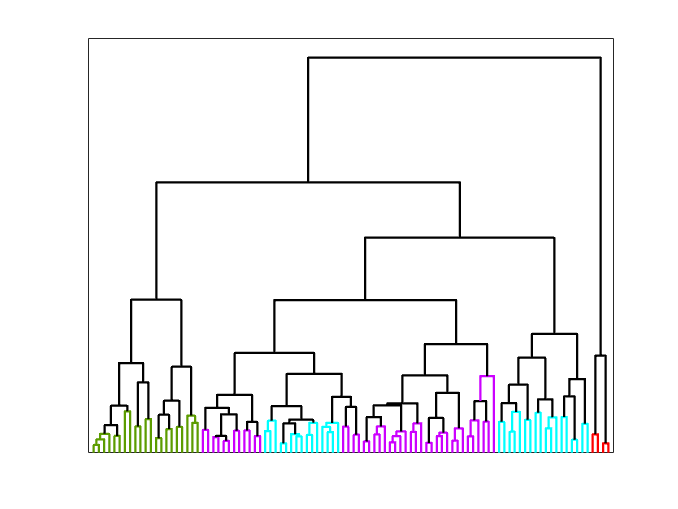



%
%============================================
% Generate HC with complete linkage
%============================================
%
tree2=linkage(numericY1,'complete');
%
% Generate clustering and drendrogram
%
figure
h2=dendrogram(tree2,0);
set(h2,'Color','k');
set(h2,'LineWidth',1.5);
for i = 1:length(h2)
    h2(i).Color = [0, 0, 0]; % RGB for black
end
% 
% Recolor based on colors of average clustering
%
for iLeaf = 1:N
	[iRow, ~] = find(tree2==iLeaf);
	set(h2(iRow), 'Color', numericY1_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"Y1 Complete Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
for i = 1:size(h2,1)
    if h2(i).Color == [0.5 1.0 0];
        h2(i).Color = [0.36 0.61 0.00];
    end
end
savefig("Y1_complete.fig");
exportgraphics(gcf, 'Y1_complete.png');

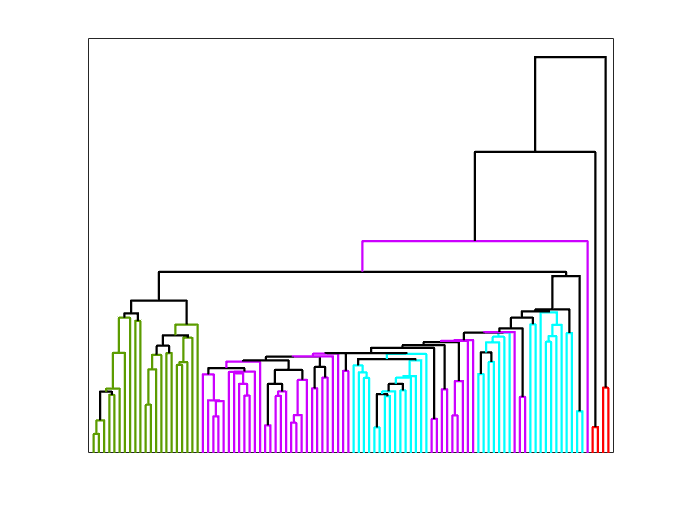


%============================================
% Generate HC with single linkage
%============================================
%
tree3=linkage(numericY1,'single');
%
% Generate clustering and drendrogram
%
figure
h3=dendrogram(tree3,0);
set(h3,'Color','k');
set(h3,'LineWidth',1.5);
% 
% Recolor based on colors of average clustering
%
for i = 1:length(h3)
    h3(i).Color = [0, 0, 0]; % RGB for black
end
for iLeaf = 1:N
	[iRow, ~] = find(tree3==iLeaf);
	set(h3(iRow), 'Color', numericY1_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"Y1 Single Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
for i = 1:size(h3,1)
    if h3(i).Color == [0.5 1.0 0];
        h3(i).Color = [0.36 0.61 0.00];
    end
end
savefig("Y1_single.fig");
exportgraphics(gcf, 'Y1_single.png');

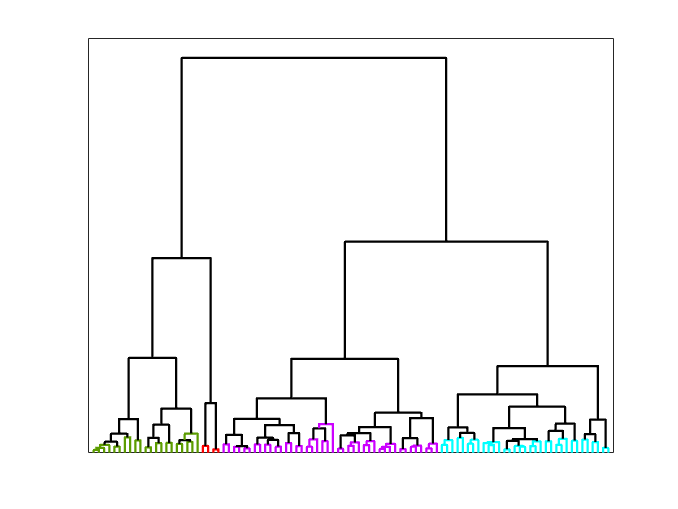


%============================================
% Generate HC with single linkage
%============================================
%
tree4=linkage(numericY1,'ward');
%
% Generate clustering and drendrogram
%
figure
h4=dendrogram(tree4,0);
set(h4,'Color','k')
set(h4,'LineWidth',1.5)
% 
% Recolor based on colors of average clustering
%
for i = 1:length(h4)
    h4(i).Color = [0, 0, 0]; % RGB for black
end
for iLeaf = 1:N
	[iRow, ~] = find(tree4==iLeaf);
	set(h4(iRow), 'Color', numericY1_color(iLeaf,:));
end
xticks([])
yticks([])
% xlabel({"Y1 Ward Linkage"});
% yticklabels({});
box on
gca.LineWidth=1;
for i = 1:size(h4,1)
    if h4(i).Color == [0.5 1.0 0];
        h4(i).Color = [0.36 0.61 0.00];
    end
end
savefig("Y1_ward.fig");
exportgraphics(gcf, 'Y1_ward.png');

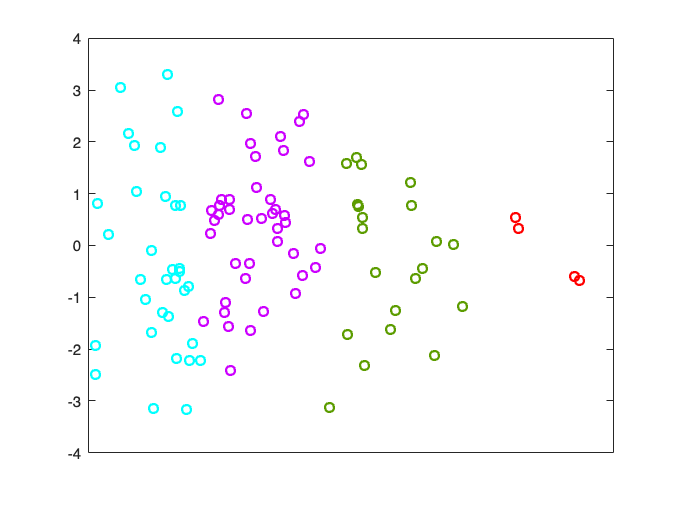


%============================================
% Perform MDS
%============================================
%
[Y e]=cmdscale(numericY1,2);

figure
hold on
for i=1:N
     plot (Y(i,1),Y(i,2), "o", "Color", numericY1_color(i,:), 'LineWidth',1.5);
    % plot(Y(iLeaf,1),Y(iLeaf,2), 'o','Color',numericY1_color(iLeaf,:), 'LineWidth',1.5);
end
xticks([])
% yticks([])
% xlabel({"Y1 MDS"});
% yticklabels({});
box on
gca.LineWidth=1;
savefig("Y1_mds.fig");
exportgraphics(gcf, 'Y1_mds.png');